T = readtable('/Users/ivankcl/Desktop/ASTRI/code/data/calibration.csv.nosync.csv')

T = 7525×35 table
    PacketCounter    SampleTimeFine      Acc_X        Acc_Y      Acc_Z       Gyr_X        Gyr_Y        Gyr_Z       Mag_X       Mag_Y       Mag_Z     VelInc_X     VelInc_Y     VelInc_Z    OriInc_q0    OriInc_q1    OriInc_q2    OriInc_q3     Pressure     Quat_q0    Quat_q1      Quat_q2      Quat_q3      Roll       Pitch         Yaw       Mat_1__1_    Mat_2__1_    Mat_3__1_    Mat_1__2_    Mat_2__2_    Mat_3__2_    Mat_1__3_


Fs = 40;
AccelerationReadings = fillmissing(table2array(T(1:end,3:5)),'previous');
AngularVelocityReadings = fillmissing(table2array(T(1:end,6:8)), 'previous');
MagneticFieldReadings = fillmissing(table2array(T(1:end, 9:11)),'previous');

imuFs = 40;
size(AccelerationReadings)

ans =         7525           3


filt = insfilterAsync;
N = size(AccelerationReadings,1);
p = zeros(N,3);
q = zeros(N,1,'quaternion');

gpsIdx = 1;

filt.ReferenceLocation = [0 0 0];
filt.State = [1;0.0084;-0.0026;1.93925e-5;0;0;0;0;0;0;0;0;0;0;0;0;9.80665e-5;9.80665e-5;1.4709975e-4;1.93925e-5;1.93925e-5;1.93925e-5;0.1;0.1;0.1;0.1;0.1;0.1];

Rmag  = 0.4;
Racc  = 610;
Rgyro = 0.76e-5;

for ii = 1:N
    
    % Predict the filter forward one time step
    predict(filt,1./imuFs);
    
    % Fuse accelerometer and gyroscope readings
    fuseaccel(filt,AccelerationReadings(ii,:),Racc);
    fusegyro(filt,AngularVelocityReadings(ii,:),Rgyro);
    
    % Fuse magnetometer at 1/2 the IMU rate
    if ~mod(ii, fix(imuFs/4))
        fusemag(filt,MagneticFieldReadings(ii,:),Rmag);
    end
    
    % Fuse GPS once per second
%     if ~mod(ii,imuFs)
%         fusegps(filt,lla(gpsIdx,:),Rpos,gpsvel(gpsIdx,:),Rvel);
%         gpsIdx = gpsIdx + 1;
%     end
    
    % Log the current pose estimate
    [p(ii,:),q(ii)] = pose(filt);
    
end

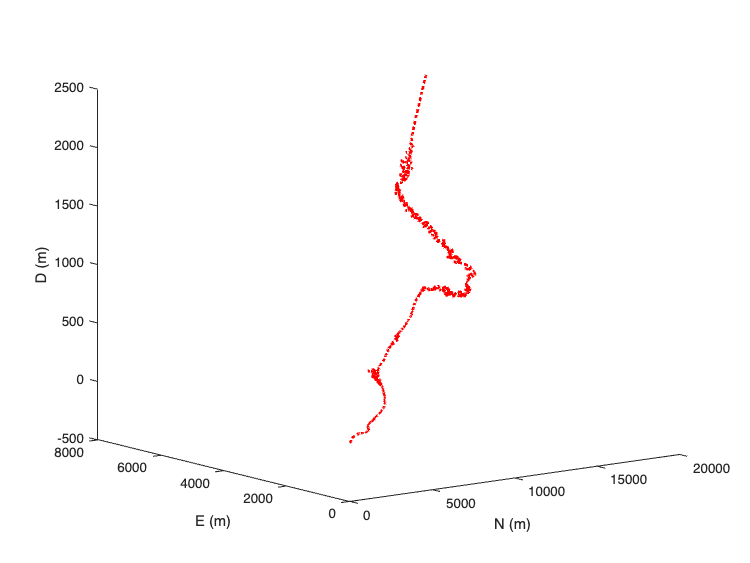

plot3(p(:,1),p(:,2),p(:,3),'r:','LineWidth',2)
xlabel('N (m)')
ylabel('E (m)')
zlabel('D (m)')